binarizeThresh = 0.6

binarizeThresh = 0.6000

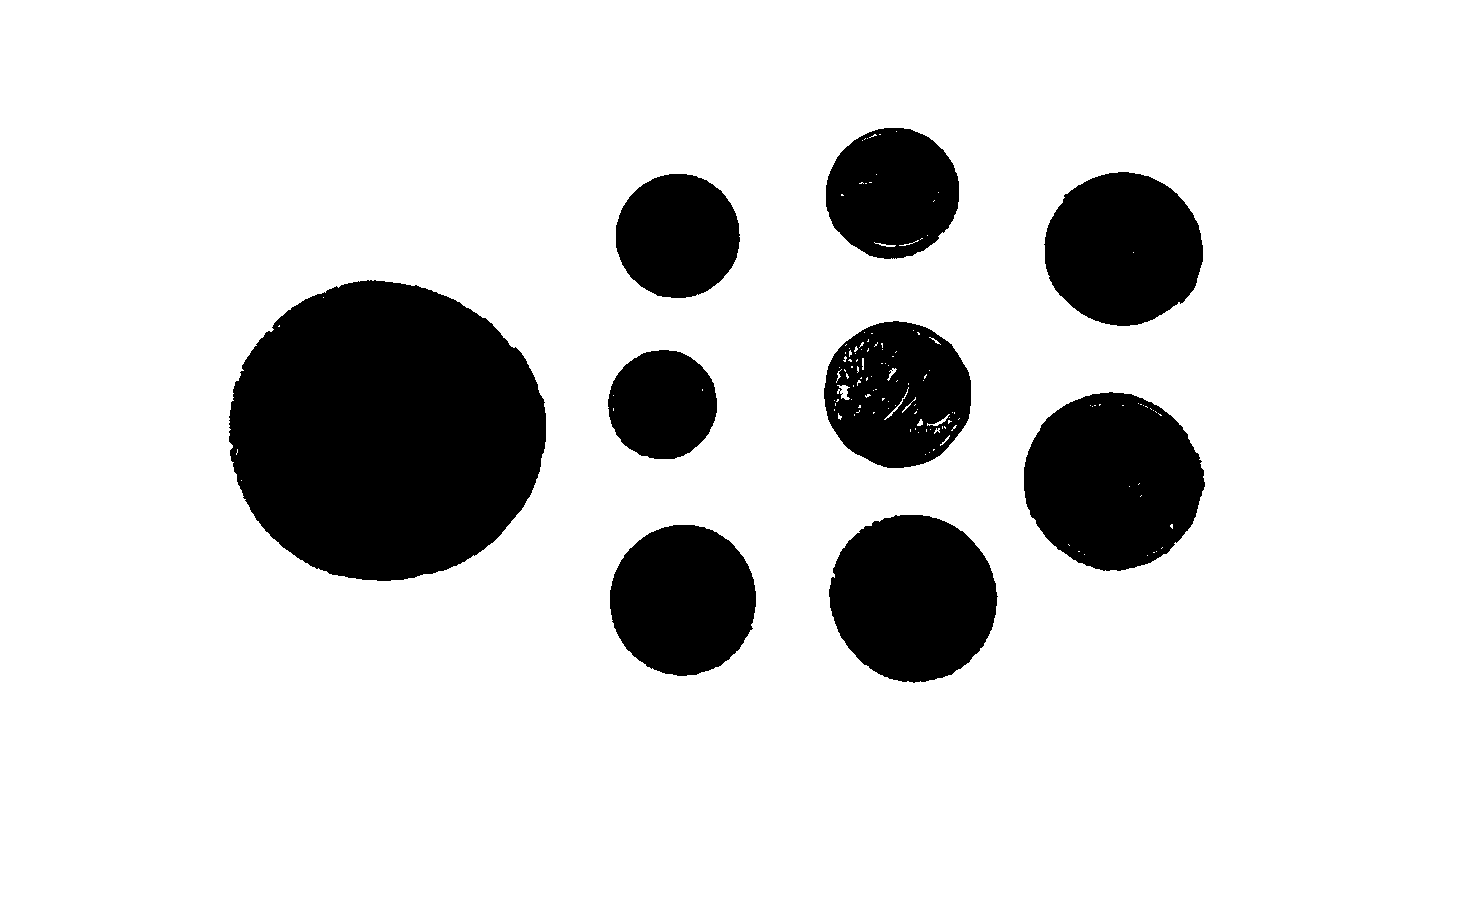

SESize = 10;



imgOrig = imread("coinsCalibrateWhite.jpg");
img = im2gray(imgOrig);
img = imbinarize(img, binarizeThresh);
imshow(img)

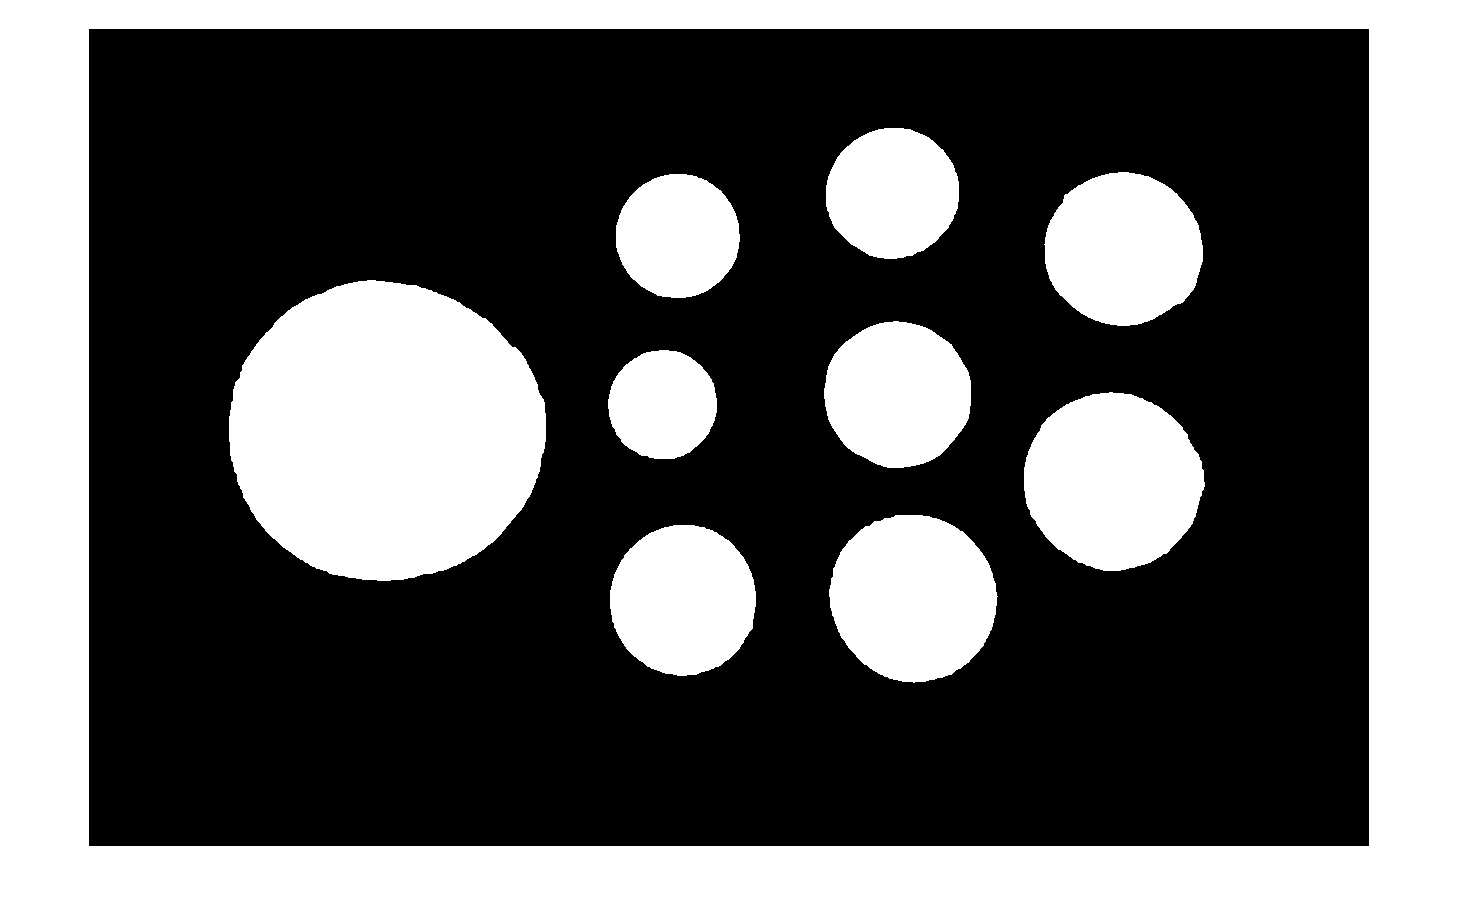


se = strel('disk', SESize);
img = ~imopen(img, se);

imshow(img);



prop = regionprops(img, 'Area', 'Centroid');

prop = struct2table(prop);

prop

prop = 9×2 table
    Area         Centroid    
    _____    ________________

    74504     297.1    403.21
     9336    574.15    376.21
    17319    594.66    571.76
    12109    589.31    207.55
    16872    809.13    366.04
    13642    804.01    164.66
    21987    824.71    569.46
    24802    1024.6    452.71
    18995      1035     220.7



oneCent = 0;
twoCent = 0;
fiveCent = 0;
tenCent = 0;
twentyCent = 0;
fiftyCent = 0;
oneEuro = 0;
twoEuro = 0;


scale = 1;

for i = 1 : numel(prop.Area(:,1))
    coin = prop.Area(i);

    if coin < 1 * scale
        oneCent = oneCent + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        twoCent = twoCent + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        tenCent = tenCent + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        fiveCent = fiveCent + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        twentyCent = twentyCent + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        oneEuro = oneEuro + 1;
    elseif coin >= 1 * scale && coin < 1 * scale
        fiftyCent = fiftyCent + 1;
    elseif coin > 1 * scale
        twoEuro = twoEuro + 1;
    end
end

oneCent

oneCent = 0

twoCent

twoCent = 0

fiveCent

fiveCent = 0

tenCent

tenCent = 0

twentyCent

twentyCent = 0

fiftyCent

fiftyCent = 0

oneEuro

oneEuro = 0

twoEuro

twoEuro = 9


total = oneCent * 0.01 + twoCent * 0.02 + fiveCent * 0.05 + tenCent * 0.1 + twentyCent * 0.2 + fiftyCent * 0.5 + oneEuro + twoEuro * 2;
fprintf('%05.2f', total); fprintf('%c', '€');

18.00€